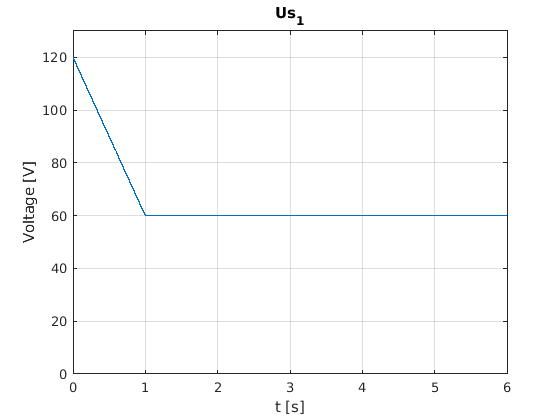

clc; clear all; close all;

R_1 = 5000; % Ohm
R_2 = 2000; % Ohm
R_3 = 1200; % Ohm
R_4 = 8000; % Ohm
R_5 = 1200; % Ohm

C_1 = 380*10^-6; % Farad
C_2 = C_1; % Farad

L_1 = 50; % Henry

Us_1_max = 120; % V
Us_1_nom = 60; % V
Us_2 = 120; % V

t_change = 1; % s, time the voltage take to change from 120 to 60V in Us1

% Initial conditions
uB = 60; % V
uC = 60; % V
i2 = 0; % A

t = 0; % s
dt = 10^-5; % s
simTime = 6; % s

idx = 1; % Counter

while t <= simTime
    
    if(t < t_change)
        uA = 120 - 60* t/t_change;
    else
        uA = 60;
    end

    uD = Us_2;
    uE = R_2 * i2;
    i1 = (uD-uA)/R_1;
    i3 = (uA-uB)/R_3;
    i4 = (uA-uB)/R_4;
    i5 = (uB-uC)/R_5;

    uBDot = 1/C_1 * (i3 + i4 - i5);
    uCDot = 1/C_2 * i5;

    i2Dot = 1/L_1 * (uA-uE);

    % Logging
    timePlot(idx) = t;
    uAPlot(idx) = uA;
    i1Plot(idx) = i1*10^3;
    i2Plot(idx) = i2*10^3;
    i3Plot(idx) = i3*10^3;
    i4Plot(idx) = i4*10^3;
    i5Plot(idx) = i5*10^3;
    
    % Time Integrate
    uB = uB + uBDot * dt;
    uC = uC + uCDot * dt;
    i2 = i2 + i2Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;

end

% Plot for Us1
plot(timePlot, uAPlot)
ylim([0 130])
xlim([0 6])
title("Us_{1}")
xlabel("t [s]")
ylabel("Voltage [V]")
grid
hold off

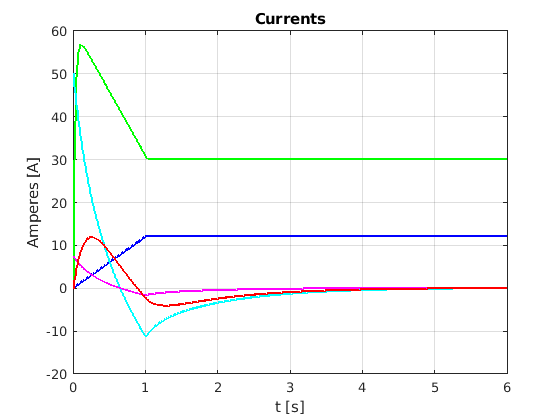


% Plot for all currents i1-i5
plot(timePlot, i1Plot, 'b', 'LineWidth', 2)
hold on
plot(timePlot, i2Plot, 'g', 'LineWidth', 2)
plot(timePlot, i3Plot, 'c', 'LineWidth', 2)
plot(timePlot, i4Plot, 'm', 'LineWidth', 2)
plot(timePlot, i5Plot, 'r', 'LineWidth', 2)
title("Currents")
xlabel("t [s]")
ylabel("Amperes [A]")
grid